# Exercises 5.6

2. Determine the equivalent nodal forces to the distributed load q.

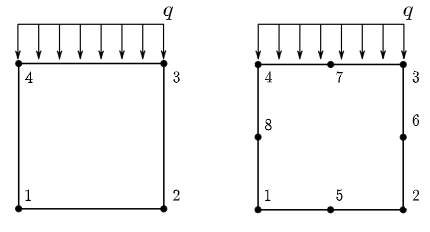

clear all
clc

syms q
C1 = [1; 3];
C2 = [1; 3; 2];
ex1 = compute_F(4,C1,q,2);
ex2 = compute_F(8,C2,q,3);
vpa(ex1, 2)

$$ans = \left(\begin{array}{c} 0\\ -1.0\,q\\ 0\\ -1.0\,q \end{array}\right)$$

vpa(ex2, 2)

$$ans = \left(\begin{array}{c} 0\\ -0.33\,q\\ 0\\ -0.33\,q\\ 0\\ -1.3\,q \end{array}\right)$$

function F = compute_F(type,C, P, q)
if type == 4
    nnodes = 2;
elseif type == 8
    nnodes = 3;
else type = 0;
end
ndof   = 2;
F      = zeros(ndof*nnodes,1);
for i = 1: q
    Q       = quadrature_lin(q);
    xi      = Q (i, 1);
    w       = Q (i, 2);
    [dN, n] = lin_shape_form(nnodes,xi);
    J       = C'*dN;
    N = zeros(nnodes*2,2);
    for j = 1: nnodes
    k = (j-1) * 2;
    I = eye(2);
    N([k+1 k+2], :) = I*n(j); 
    end
    jn = [0 -J(1)]';    % ...
    F = F + N*P*jn*det(J)*w;
end
end  